# DMFT+NRG

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

In this tutorial, we will perform the dynamical mean-field theory (DMFT) calculations by using our NRG code as an impurity solver. Such approach is called DMFT+NRG.

*Note:* The calculations for Exercises (b) and (c) will take quite long time; it took about 50 minutes on my laptop.

## Exercise (a): Complete the DMFT+NRG function

There is a function `DMFT_Hubbard_Ex.m`, contained in the same sub-directory together with this script. The function is designed to perforem DMFT+NRG calculations on the Hubbard model on a lattice whose non-interacting density of states is semi-elliptic,


$$\rho(\epsilon) = \frac{2}{\pi D^2} \theta (D - |\epsilon|) \sqrt{D^2 - \epsilon^2} .$$


Here we use $D :=1$ as the energy unit. Such semi-elliptic $\rho(\epsilon)$ comes from the Bethe lattice with infinite coordination number. However, the actual lattice geometry is not important here, since the only information on the lattice relevant to this type of calculation is the non-interacting density of states.

Complete `DMFT_Hubbard_Ex.m`, by filling out the parts enclosed by the comments `TODO (start)` and `TODO (end)`.

Let's consider the simplest example of $U = 0$ and $\mu = 0$. Actually, this example is somehow trivial; the DMFT self-consistency loop completes in two iterations regardless of the initial hybridization function. (**Quick exercise:** why?)

clear

% system parameters
U = 0;
mu = 0; 
T = 1e-4;
D = 1;

% initial hybridization function
ozin = [-1;1];
RhoV2in = [1;1]/2*(D/2)^2;

% NRG parameters
Lambda = 4;
N = 30;
Nkeep = 300;

% run DMFT+NRG
[ocont,RhoV2s,iscvg] = DMFT_Hubbard_Ex (U,mu,T,D,ozin,RhoV2in,Lambda,N,Nkeep);

Here I don't show the log message since it's too long.

First check whether the DMFT self-consistency is achieved.

disp(iscvg);

   1



Let's plot the local spectral functions $A (\omega) = (2/D)^2 \Delta'' (\omega)$. Note that this relation between $A(\omega)$ and $\Delta''(\omega)$ holds only for the semi-elliptic $\rho(\epsilon)$ we've chosen.

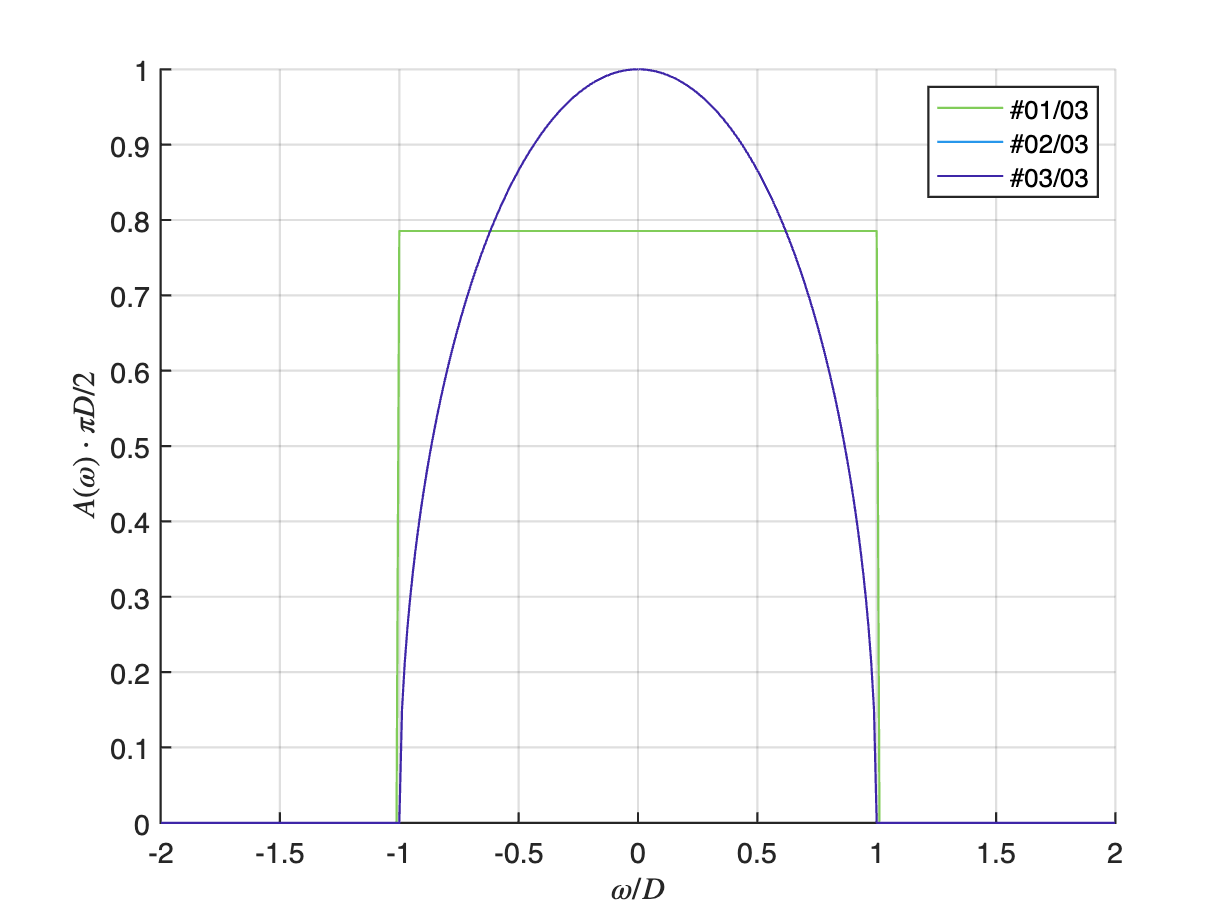

cmap = parula(round(size(RhoV2s,2)*1.2));
cmap = flipud(cmap(1:size(RhoV2s,2),:)); % to avoid too bright colors
legs = cell(1,size(RhoV2s,2));

figure;
hold on;
for itd = (1:size(RhoV2s,2))
    plot(ocont/D,RhoV2s(:,itd)/((D/2)^2)*(pi*D/2), ...
        'LineWidth',1,'Color',cmap(itd,:));
    legs{itd} = ['#',sprintf('%02i/%02i',[itd size(RhoV2s,2)])];
end
hold off;
grid on;
set(gca,'LineWidth',1,'FontSize',13);
legend(legs);
xlabel('$\omega / D$','Interpreter','latex');
ylabel('$A(\omega) \cdot \pi D/2$','Interpreter','latex');
xlim([-1 1]*(2*D));

Indeed, the converged spectral function equals to the non-interacting density of states, i.e., $A(\omega) = \rho(\omega)$. That is, the DMFT is exact for non-interacting systems.

In the plot above,  we multiplied $\pi D/2$ to the spectral functions so that the converged curve takes a value of 1 at the Fermi level ($\omega = 0$); it's in the same spirit as we multiplied $\pi \Delta_0$ in the previous tutorial on the SIAM with a box-shaped hybridization function.

## Exercise (b): Obtain the DMFT+NRG solutions starting from the $U = 0$ result

Let's use the $U = 0$ result of the hybridization function as the initial hybridization function for DMFT self-consistency loops. Obtain the DMFT+NRG solutions of the Hubbard model at half filling (i.e., $\langle \hat{n}_i \rangle = 1$), for several different values of $U/D = (2:0.3:3.5)$. Fix $T = 10^{-4} D$ and $D := 1$. Plot the converged spectral functions. What's happening? Also, discuss the convergence behaviors depending on $U$.

## Exercise (c): Obtain the DMFT+NRG solutions starting from the $U = 3.5 D$ result

Obtain the DMFT+NRG solutions for the same system parameters as used in Exercise (b), except that we use the $U = 3.5D$ result of the hybridization function, one of the results from Exercise (b) above, as the initial hybridization function, instead of the $U = 0$ result. How do the converged spectral functions look like, in comparison with the results of Exercise (b)?